%wind导入历史行情序列
w = windmatlab;
begintime='20191014';     %时间序列开始日
endtime='20201014';       %时间序列结束日
[w_wsd_data,w_wsd_codes,w_wsd_fields,w_wsd_times,w_wsd_errorid] = w.wsd('600029.SH','close',begintime,endtime,'Priceadj=B','tradingcalendar=SSE','Days=Trading')  %获取收盘价（后复权）

w_wsd_data =    11.8037
   11.7697
   11.6676
   11.7697
   11.4805
   11.3615
   11.3615
   11.2424
   11.2424
   11.2084


w_wsd_codes = 1×1 cell 数组
    {'600029.SH'}


w_wsd_fields = 1×1 cell 数组
    {'CLOSE'}


w_wsd_times =       737712
      737713
      737714
      737715
      737716
      737719
      737720
      737721
      737722
      737723


w_wsd_errorid = 0

SA = [w_wsd_times,w_wsd_data]

SA = 	1.0e+05 *

    7.3771    0.0001
    7.3771    0.0001
    7.3771    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001


clearvars -except SA

%数据清洗
SA = rmmissing(SA);    %清除空值
time = datetime(SA(:,1),'ConvertFrom','datenum');   %将数据第一列转为datetime数组并定义为time
prices = SA(:,2);
T = timetable(time,prices);
clearvars -except SA prices time T

econometricModeler

%模型模拟
md1 = GARCH_LogReturns

md1 =   garch - 属性:

     Description: "GARCH(1,1) Conditional Variance Model (t Distribution)"
    Distribution: Name = "t", DoF = 4.03098
               P: 1
               Q: 1
        Constant: 0.000108528
           GARCH: {0.610041} at lag [1]
            ARCH: {0.153488} at lag [1]
          Offset: 0

V0 = infer(md1,LogReturns);
[V,Y] = simulate(md1,252,'NumPaths',10000,'E0',LogReturns,'V0',V0)

V =     0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.0006    0.0003    0.0003    0.0004    0.0003    0.0003    0.0003    0.0003    0.0006    0.0004    0.0003    0.0004    0.0003    0.0004    0.0003    0.0003    0.0003    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0007    0.0003    0.0004    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0005    0.0004    0.0003    0.0003    0.0003    0.0004    0.0003    0.0003    0.0003    0.0004    0.0003    0.0003    0.0003    0

Y =    -0.0401   -0.0018   -0.0116    0.0280    0.0008    0.0097    0.0050   -0.0021   -0.0407    0.0167    0.0061   -0.0157   -0.0025    0.0259    0.0018    0.0017   -0.0032   -0.0274   -0.0066   -0.0074    0.0009    0.0027   -0.0029    0.0136   -0.0044    0.0023   -0.0078   -0.0509   -0.0042    0.0151    0.0029    0.0047   -0.0077   -0.0133    0.0077    0.0086   -0.0307   -0.0208    0.0075   -0.0003   -0.0033    0.0183   -0.0013    0.0047    0.0098   -0.0239    0.0002   -0.0005    0.0038    0.0046
    0.0160   -0.0166   -0.0123   -0.0020   -0.0022    0.0162   -0.0052   -0.0113    0.0083    0.0026    0.0154    0.0444    0.0147    0.0118   -0.0060   -0.0241    0.0118    0.0022    0.0272    0.0201    0.0173   -0.0029    0.0130   -0.0040    0.0037   -0.0014    0.0049    0.0954   -0.0015   -0.0077    0.0123   -0.0191   -0.0009   -0.0253    0.0167    0.0066    0.0068   -0.0001    0.0091   -0.0062   -0.0295   -0.0076    0.0147    0.0215    0.0088   -0.0118    0.0073   -0.0226    0.0044    0

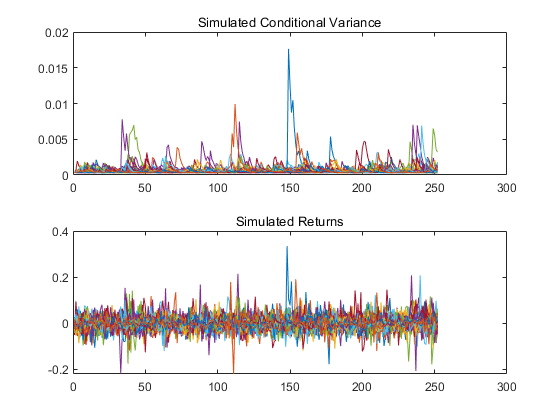

%画出10个路径上的模拟值
figure
subplot(2,1,1)
plot(V(:,1:100))
title('Simulated Conditional Variance')
subplot(2,1,2)
plot(Y(:,1:100))
title('Simulated Returns')

%计算预测波动率和历史波动率
tradingDays = 252;
LogReturns = rmmissing(LogReturns);
Fvol = mean(std(Y))*sqrt(tradingDays);
Hvol1Y = std(LogReturns)*sqrt(tradingDays);
disp(['Forecasted 1-year volatility = ' num2str(Fvol*100,4) '%'])

Forecasted 1-year volatility = 33.38%


disp(['Historical 1-year volatility = ' num2str(Hvol1Y*100,4) '%'])

Historical 1-year volatility = 31.8%
